# Load Laser Scan Data from File

Load a down-sampleed data set consisting of laser scans collected from a mobile robot in an indoor environment. The average displacement between every two scans is around 0.6 meters

% uncomment the below line for using the warehouse dataset
load('offlineSlamData.mat'); 

whos("lines")



# Run SLAM Algorithm, Construct Optimized Map and Plot Trajectory of the Robot

maxLidarRange = 8;
mapResolution = 20;
slamAlg = lidarSLAM(mapResolution, maxLidarRange);
slamAlg.LoopClosureThreshold = 210;  
slamAlg.LoopClosureSearchRadius = 8;

# Observe the Map building Process with initial 10 scans

for i=1:10
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i});
    if isScanAccepted
        fprintf('Added scan %d \n', i);
    end
end

figure;
show(slamAlg);
title({'Map of the Environment','Pose Graph for Initial 10 Scans'});

# Observe the effect of loop closures and the optimization process

for i=10:length(scans)

Added scan 1 
Added scan 2 
Added scan 3 
Added scan 4 
Added scan 5 
Added scan 6 
Added scan 7 
Added scan 8 
Added scan 9 
Added scan 10 


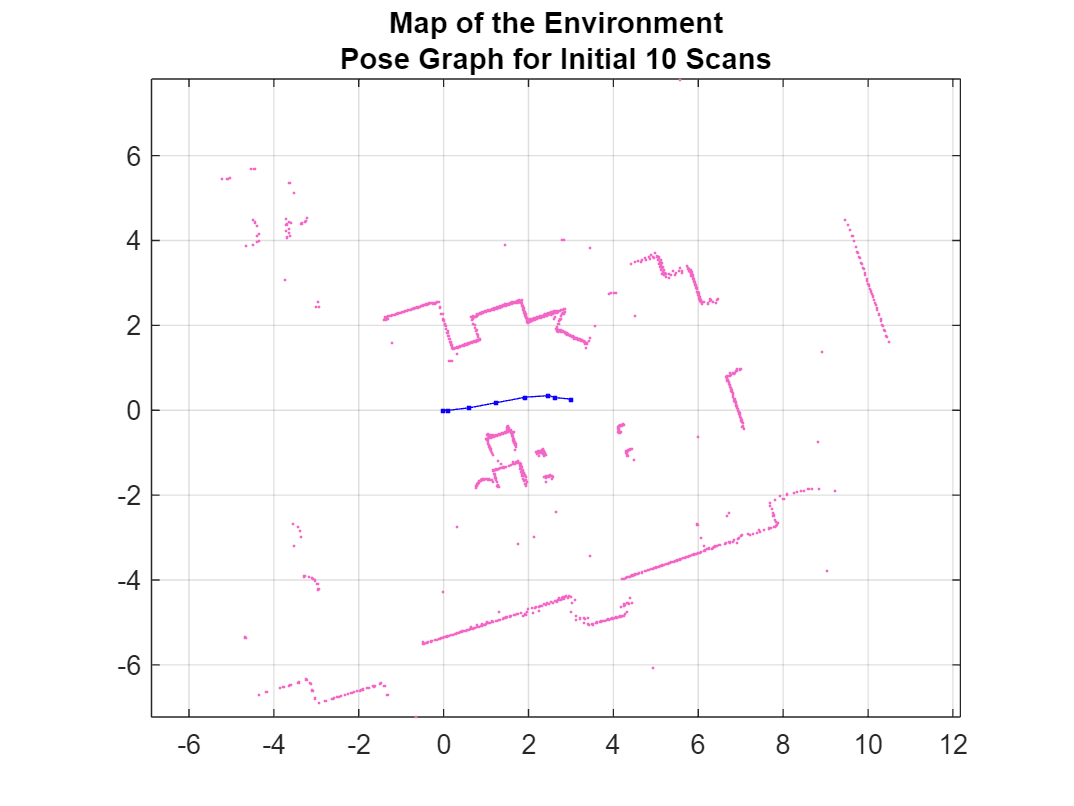

    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i});
    if ~isScanAccepted
        continue;
    end

end 

# Visualize the Contructed Map and Trajectory of the Robot

figure
show(slamAlg);
title({'Final Built Map of the environment', 'Trajectory of the Robot'});

# Build Occupancy Grid Map

[scans, optimizedPoses]  = scansAndPoses(slamAlg);
map = buildMap(scans, optimizedPoses, mapResolution, maxLidarRange);
figure; 
show(map);
hold on
show(slamAlg.PoseGraph, 'IDs', 'off');
hold off
title('Occupancy Grid Map Built Using Lidar SLAM');

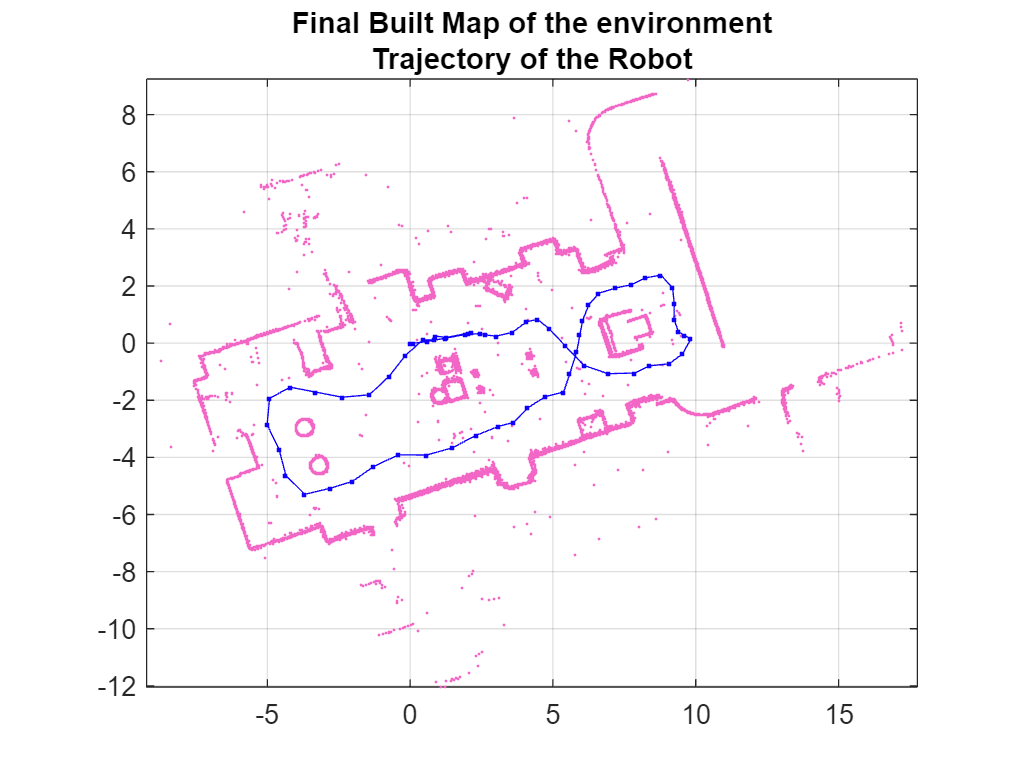

% Assuming optimizedPoses is already available (Nx3: [x y theta])

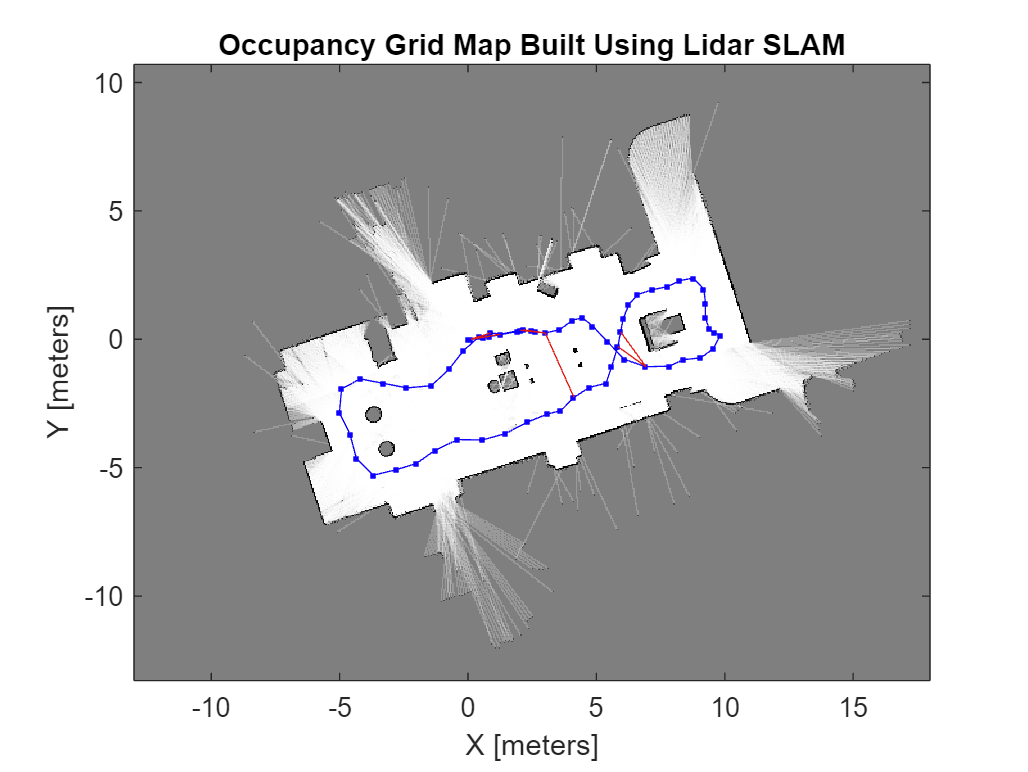

x = optimizedPoses(:, 1);
y = optimizedPoses(:, 2);

% Plot the X-Y trajectory
figure;
plot(x, y, 'b-', 'LineWidth', 2); % Trajectory as a blue line
hold on;
scatter(x(1), y(1), 50, 'g', 'filled');   % Start point (green)
scatter(x(end), y(end), 50, 'r', 'filled'); % End point (red)
title('Optimized Robot Trajectory on X-Y Plane');

xlabel('X (meters)');
ylabel('Y (meters)');
grid on;
axis equal;
legend('Trajectory', 'Start', 'End');

trajectory = [x, y];
writematrix(trajectory, 'trajectory.csv');

theta = optimizedPoses(:, 3);

% Plot orientation arrows every N steps
N = 2;
quiver(x(1:N:end), y(1:N:end), cos(theta(1:N:end)), sin(theta(1:N:end)), 0.3, 'k');

### Basic Filtering

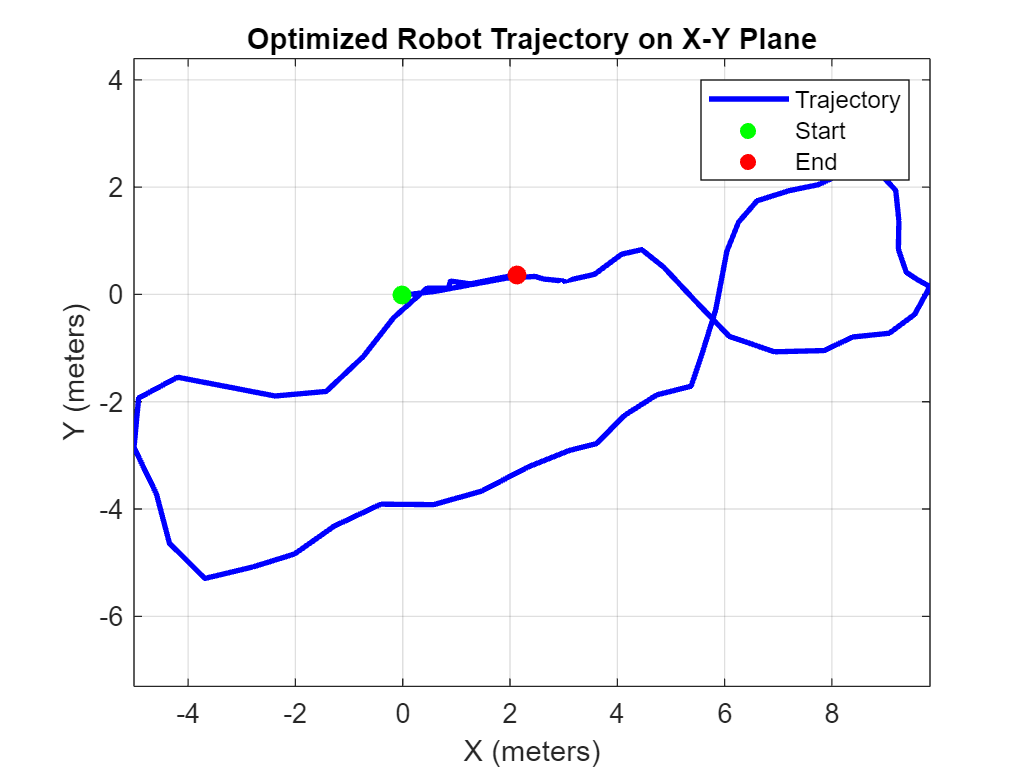

x_smooth = smoothdata(x, 'movmean', 10);  % Moving average filter
y_smooth = smoothdata(y, 'movmean', 10);

% Plot smoothed path

figure;
plot(x, y, 'r--', x_smooth, y_smooth, 'b-', 'LineWidth', 2);
legend('Original Trajectory', 'Smoothed Trajectory');
title('Smoothed Trajectory using Moving Average');
xlabel('X (m)'); ylabel('Y (m)');
grid on; axis equal;

### Curve Fitting (B-spline Interpolation)

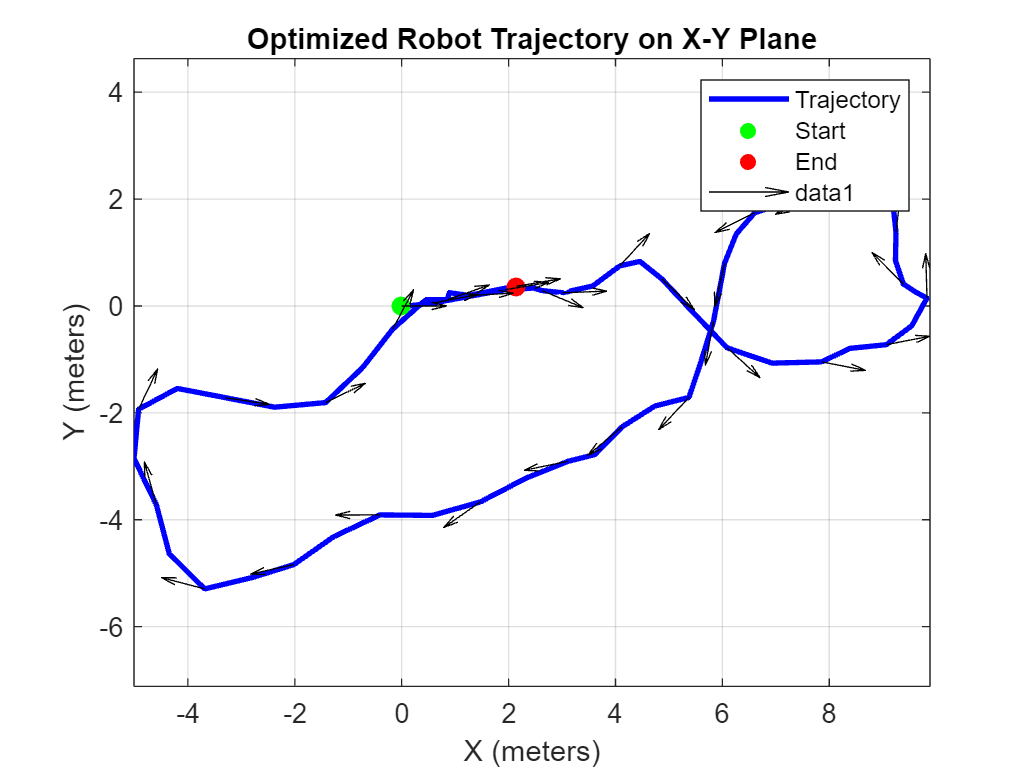

% Use parameter t as the path index
t = 1:length(x);

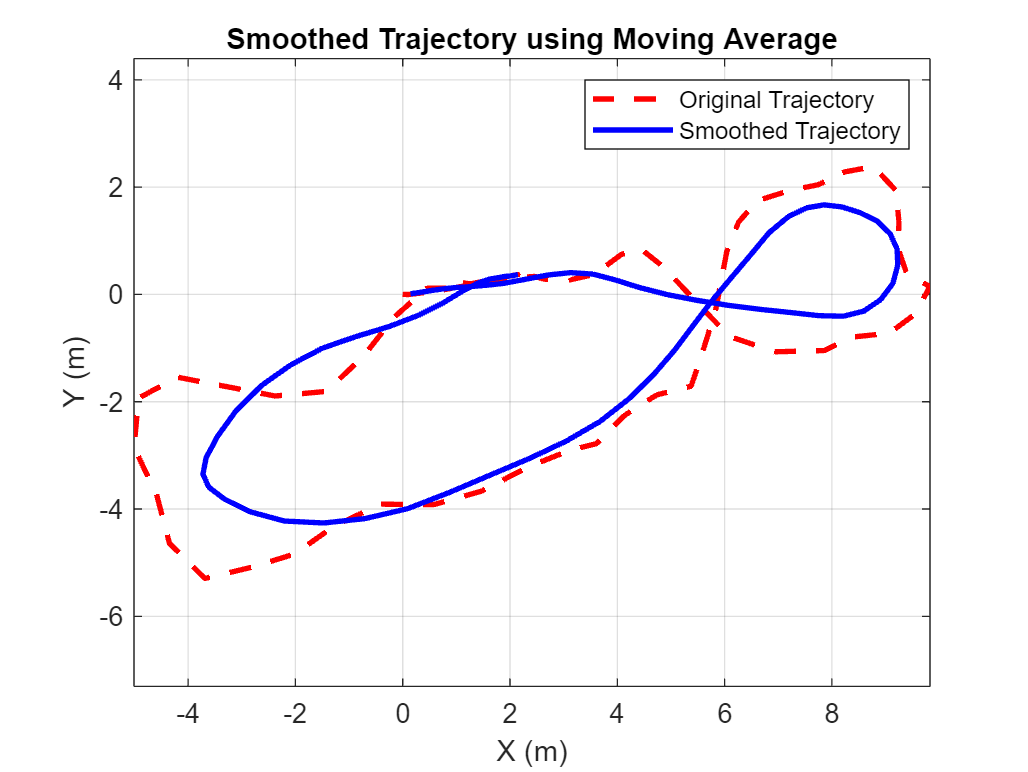


% Fit splines to x and y
x_fit = spline(t, x);
y_fit = spline(t, y);

% Evaluate the spline at finer resolution
tt = linspace(1, length(x), 30); % More points for smoother curve
x_spline = ppval(x_fit, tt);
y_spline = ppval(y_fit, tt);

% Plot
figure;

plot(x, y, 'r--', x_spline, y_spline, 'b-', 'LineWidth', 2);
legend('Original', 'Spline Smoothed');
title('Trajectory Smoothed Using Cubic Spline');
axis equal; grid on;

### Putting a Robot to follow the above trajectory

% Approximate heading theta between points
dx = gradient(x_spline);
dy = gradient(y_spline);
theta_spline = atan2(dy, dx); % compute heading from gradients

% Assembe [x y theta] waypoints
refPoses = [x_spline(:), y_spline(:), theta_spline(:)];

### Setting up the mobile Robot

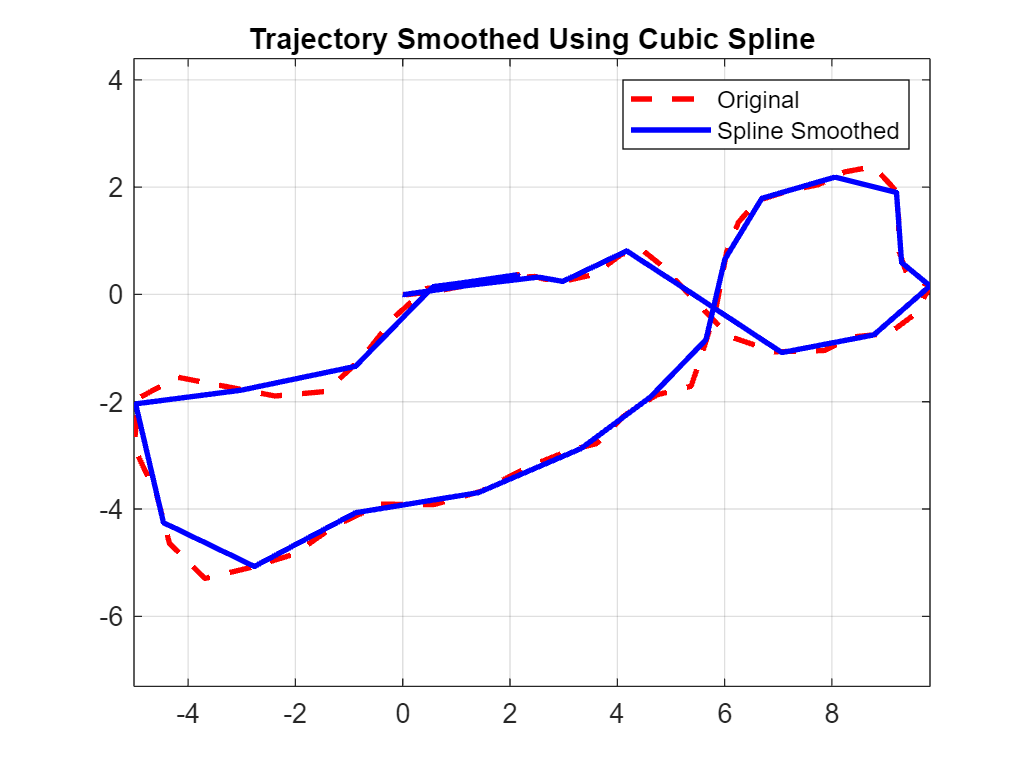

sampleTime = 0.3;
robotInitialPose = refPoses(1,:); % start at first waypoint
goalRadius = 0.1;
robotPose = robotInitialPose';

% Create unicycle kinematic model (for 4-wheeled robot)
robot = unicycleKinematics("VehicleInputs","VehicleSpeedHeadingRate");

### Set up pure pursuit Controller

controller = controllerPurePursuit;
controller.Waypoints = refPoses(:, 1:2);
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 1.5;
controller.LookaheadDistance = 0.8;

### Simulation Loop

poses = [];
odom = [];

goal = refPoses(end, 1:2);
distanceToGoal = norm(robotPose(1:2) - goal);

while distanceToGoal > goalRadius
    
    % Get Control Commands
    [v, w] = controller(robotPose);

    % Simulate unicycle motion
    vel = derivative(robot, robotPose, [v, w]);
    robotPose = robotPose + vel * sampleTime;

    % log pose and odometry
    poses = [poses; robotPose'];
    odom = [odom; v, w];

    % update distance to goal
    distanceToGoal = norm(robotPose(1:2) - goal);

end

### Plot Trajectory

figure;
plot(x_spline, y_spline, 'b--', 'LineWidth', 2); hold on;
plot(poses(:,1), poses(:,2), 'r-', 'LineWidth', 2);
legend('Smoothed Path', '4-Wheel Robot Trajectory');
xlabel('X (m)'); ylabel('Y (m)');
title('Path Tracking with 4-Wheeled Robot (Unicycle Model)');
grid on; axis equal;

### Simulation with Visualization

% Create real-time external figure
fig = figure('Name', 'Robot Animation', 'Visible', 'on');
axis equal; grid on;
xlim([min(x_spline)-1, max(x_spline)+1]);
ylim([min(y_spline)-1, max(y_spline)+1]);
xlabel('X (m)'); ylabel('Y (m)');
title('4-Wheel Robot Tracking Animated');
plot(x_spline, y_spline, 'b--', 'LineWidth', 1.5); hold on;

robotMarker = plot(robotPose(1), robotPose(2), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
headingArrow = quiver(robotPose(1), robotPose(2), cos(robotPose(3)), sin(robotPose(3)), 0.4, 'k', 'LineWidth', 1.5);

% Simulation loop
while distanceToGoal > goalRadius
    % Control, simulate, update pose
    [v, w] = controller(robotPose);
    vel = derivative(robot, robotPose, [v, w]);
    robotPose = robotPose + vel * sampleTime;

    % Logging and distance update
    poses = [poses; robotPose'];
    odom = [odom; v, w];
    distanceToGoal = norm(robotPose(1:2) - goal);

    % Update plots
    set(robotMarker, 'XData', robotPose(1), 'YData', robotPose(2));
    set(headingArrow, 'XData', robotPose(1), 'YData', robotPose(2), ...
                      'UData', cos(robotPose(3)), 'VData', sin(robotPose(3)));
    drawnow;
    pause(0.01);  % Give renderer time to update
end


### Save Odometry

% odometryData = [poses, odom];
% save('odometry_4whell_path.mat', 'odometryData');

# CSAIL-Newcarmen data

### CSAIL dataset

% Following is the dataset from CSAIL lab by Cyrill Stachniss
filepath = '../csail-newcarmen.log.gz'
gunzip(filepath);

% load the log file in MATLAB
fid = fopen('../csail-newcarmen.log', 'r'); % Open the file for reading
data = textscan(fid, '%s', 'Delimiter', '\n'); % Read all lines
disp(data{1}(1:30))

fclose(fid);

lines = data{1}; % Extract text lines

% extract laser scan data
laserScans = {}; % Initialize storage for scans
for i = 1:length(lines)
    if contains(lines{i}, 'ROBOTLASER1') % Check if the line contains a laser scan
        laserScans{end+1} = strsplit(lines{i}); % Split by spaces
    end
end

checking how many value seach FLASER line contains

for i = 1:min(10, length(laserScans))
    disp(laserScans{i});
end

% convert the data to MATLAB format
numScans = length(laserScans);

scanData = [];
for i = 1:numScans
    values = str2double(laserScans{i}(2:end)); % Convert string to double
    if length(values) >= 180 % Ensure we have enough values
        scanData(i, :) = values(1:180); % Append valid scans
    else
        warning("Skipping scan %d: Not enough readings (%d found)", i, length(values));
        continue;
    end
end

save('../csail-newcarmen.mat', 'scanData');


% load the data
load('./csail-newcarmen.mat')
data = load('./csail-newcarmen.mat');
laserScans_data = data.scanData;

numScans = size(laserScans_data, 2)


% Parameters for SLAM
maxLidarRange = 8;   % Adjust based on your sensor
mapResolution = 20;   % Map resolution in cells per meter

% Initialize the lidarSLAM object
slamObj = lidarSLAM(mapResolution, maxLidarRange);
slamObj.LoopClosureThreshold = 80;  % Set loop closure sensitivity
slamObj.LoopClosureSearchRadius = 5; % Search radius for loop closure

% initialize SLAM parameters
numScans = size(laserScans_data, 1); % Number of scans
numRanges = size(laserScans_data, 2); % Number of measurements per scan
angles = linspace(-pi, pi, numRanges); % Generate angle values for scan

% Process each laser scan and add it to the SLAM algorithm
scans = {};
for i = 1:5:numScans
    % Ensure all values are nonnegative
    validRanges = max(laserScans_data(i, :), 0); % Clip negative values to zero
     % Check if scan is valid (avoid mostly empty scans)
    if sum(validRanges) > 10 % Ensure at least some valid readings
        scan = lidarScan(validRanges, angles); % Create lidarScan object
        scans{end+1} = scan; % Store scan
        addScan(slamObj, scan); % Add scan to SLAM
    else
        warning("Skipping scan %d: Mostly empty readings.", i);
    end
end
% Build the optimized map

[scansOptimized, optimizedPoses] = scansAndPoses(slamObj);


% Plot the optimized trajectory
figure;
plot(optimizedPoses(:,1), optimizedPoses(:,2), 'b-', 'LineWidth', 1);
hold on;
% scatter(optimizedPoses(:,1), optimizedPoses(:,2), 10, 'r', 'filled');
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Optimized Trajectory');
axis equal;
grid on;

# PID Controller Simulink Design

% MATLAB Equivalent of the PIDController for Trajectory Tracking
% Save this as a function file: PIDController.m


function [v, omega, prevAngleError, angleErrorSum, prevVError, vErrorSum, prevDistance] = PIDController(robotState, targetPoint, dt, prevAngleError, angleErrorSum, prevVError, vErrorSum, prevDistance)
    % Unpack robot state
    x = robotState(1);
    y = robotState(2);
    theta = robotState(3);

    x_target = targetPoint(1);
    y_target = targetPoint(2);

    % Desired forward velocity
    v_desired = 5.0;

    %% --- Angular control (omega) ---
    angle_to_target = atan2(y_target - y, x_target - x);
    angle_error = atan2(sin(angle_to_target - theta), cos(angle_to_target - theta));
    angle_error_deriv = (angle_error - prevAngleError) / dt;
    angleErrorSum = angleErrorSum + angle_error * dt;
    angleErrorSum = min(max(angleErrorSum, -1.0), 1.0); % Anti-windup
    prevAngleError = angle_error;

    % PID gains for angular velocity
    kp_omega = 2.0;
    ki_omega = 1.0;
    kd_omega = 0.6;
    omega = kp_omega * angle_error + ki_omega * angleErrorSum + kd_omega * angle_error_deriv;
    omega = min(max(omega, -pi), pi);

    %% --- Linear velocity control ---
    dist_to_target = sqrt((x_target - x)^2 + (y_target - y)^2);
    v_current = (prevDistance - dist_to_target) / dt;
    prevDistance = dist_to_target;

    v_error = v_desired - v_current;
    v_error_deriv = (v_error - prevVError) / dt;
    vErrorSum = vErrorSum + v_error * dt;
    vErrorSum = min(max(vErrorSum, -2.0), 2.0); % Anti-windup
    prevVError = v_error;

    % PID gains for linear velocity
    kp_v = 1.0;
    ki_v = 0.5;
    kd_v = 0.2;
    v = kp_v * v_error + ki_v * vErrorSum + kd_v * v_error_deriv;

    % Reduce speed when not aligned with target
    v = v * cos(angle_error);

    % Clamp final velocity
    v = min(max(v, 0.2), 5.0);
end


# LQR Controller Simulink Design

% MATLAB Equivalent of the LQRController for Trajectory Tracking
% Save this as a function file: LQRController.m

function [v, omega] = LQRController(robotState, targetPoint)
    % Inputs:
    %   robotState = [x; y; theta]
    %   targetPoint = [x_target; y_target]

    x = robotState(1);
    y = robotState(2);
    theta = robotState(3);

    x_target = targetPoint(1);
    y_target = targetPoint(2);

    % LQR Gain matrix (2x3)
    K = [1.5, 0.0, 0.0;
         0.0, 1.5, 2.0];

    % Global error
    dx = x_target - x;
    dy = y_target - y;
    error_global = [dx; dy];

    % Rotation matrix to robot frame
    c = cos(theta);
    s = sin(theta);
    R = [c, s; -s, c];
    error_robot = R * error_global;

    % Theta error
    angle_to_target = atan2(dy, dx);
    theta_error = atan2(sin(angle_to_target - theta), cos(angle_to_target - theta));

    % Form error state
    error_state = [error_robot; theta_error];

    % Control input via LQR gains
    v_r = K(1, :) * error_state;
    v_l = K(2, :) * error_state;

    % Convert to unicycle model control inputs
    v = (v_r + v_l) / 2;
    omega = (v_r - v_l) / 0.2;  % 0.2m wheel base

    % Saturation
    v = max(0.2, min(v, 5.0));
    omega = min(max(omega, -pi), pi);
end


# FastMPC Controller Simulink Design

% MATLAB Equivalent of the FastMPCController for Speed-Prioritized Trajectory Tracking
% Save this as a function file: FastMPCController.m

function [best_v, best_omega, last_v, last_omega] = FastMPCController(robotState, targetPoint, dt, last_v, last_omega)
    % Unpack current state
    x = robotState(1);
    y = robotState(2);
    theta = robotState(3);

    x_target = targetPoint(1);
    y_target = targetPoint(2);

    % MPC parameters
    N = 20;  % Prediction horizon

    % Cost weights (speed-prioritized)
    w_pos = 0.5;
    w_theta = 1.0;
    w_v = 0.05;
    w_omega = 0.1;
    velocity_bias = 0.3;  % Reward for high velocity

    % Control limits
    v_min = 0.0;
    v_max = 5.0;
    omega_min = -pi;
    omega_max = pi;

    % Control search ranges (favoring acceleration)
    v_range_min = max(v_min, last_v - 0.3);
    v_range_max = min(v_max, last_v + 0.7);
    v_options = linspace(v_range_min, v_range_max, 5);
    omega_options = linspace(max(omega_min, last_omega - 0.5), min(omega_max, last_omega + 0.5), 7);

    % Initialize best control
    best_cost = inf;
    best_v = last_v;
    best_omega = last_omega;

    for vi = 1:length(v_options)
        for wi = 1:length(omega_options)
            v = v_options(vi);
            omega = omega_options(wi);

            pred_x = x;
            pred_y = y;
            pred_theta = theta;
            total_cost = 0;

            for i = 0:N-1
                % Predict next state
                pred_x = pred_x + v * cos(pred_theta) * dt;
                pred_y = pred_y + v * sin(pred_theta) * dt;
                pred_theta = pred_theta + omega * dt;

                % Errors
                pos_error = sqrt((x_target - pred_x)^2 + (y_target - pred_y)^2);
                desired_theta = atan2(y_target - pred_y, x_target - pred_x);
                theta_error = atan2(sin(desired_theta - pred_theta), cos(desired_theta - pred_theta));

                % Smoothness
                v_change = abs(v - last_v);
                omega_change = abs(omega - last_omega);

                % Reward for speed
                velocity_reward = -velocity_bias * v / v_max;

                % Step cost
                step_cost = w_pos * pos_error + w_theta * abs(theta_error) + w_v * v_change + w_omega * omega_change + velocity_reward;
                discount = 0.9 ^ i;
                total_cost = total_cost + discount * step_cost;
            end

            % Update best control
            if total_cost < best_cost
                best_cost = total_cost;
                best_v = v;
                best_omega = omega;
            end
        end
    end

    % Update memory for next call
    last_v = best_v;
    last_omega = best_omega;
end


# MPC Controller Simulink Design

% MATLAB Equivalent of the MPCController for Trajectory Tracking
% Save this as a function file: MPCController.m

function [best_v, best_omega, last_v, last_omega] = MPCController(robotState, targetPoint, dt, last_v, last_omega)
    % Unpack state
    x = robotState(1);
    y = robotState(2);
    theta = robotState(3);
    
    x_target = targetPoint(1);
    y_target = targetPoint(2);

    % MPC Parameters
    N = 10;  % Prediction horizon

    % Weights
    w_pos = 1.0;
    w_theta = 1.5;
    w_v = 0.1;
    w_omega = 0.2;

    % Control limits
    v_min = 0.2; v_max = 5.0;
    omega_min = -pi; omega_max = pi;

    % Discretized control space
    v_options = linspace(max(v_min, last_v - 0.5), min(v_max, last_v + 0.5), 5);
    omega_options = linspace(max(omega_min, last_omega - 0.5), min(omega_max, last_omega + 0.5), 7);

    % Initialize best control
    best_cost = inf;
    best_v = last_v;
    best_omega = last_omega;

    % Evaluate control sequences
    for vi = 1:length(v_options)
        for wi = 1:length(omega_options)
            v = v_options(vi);
            omega = omega_options(wi);

            pred_x = x;
            pred_y = y;
            pred_theta = theta;
            total_cost = 0;

            for i = 0:N-1
                % Predict next state
                pred_x = pred_x + v * cos(pred_theta) * dt;
                pred_y = pred_y + v * sin(pred_theta) * dt;
                pred_theta = pred_theta + omega * dt;

                % Compute errors
                pos_error = sqrt((x_target - pred_x)^2 + (y_target - pred_y)^2);
                desired_theta = atan2(y_target - pred_y, x_target - pred_x);
                theta_error = atan2(sin(desired_theta - pred_theta), cos(desired_theta - pred_theta));

                % Control smoothness
                v_change = abs(v - last_v);
                omega_change = abs(omega - last_omega);

                % Cost with discount
                step_cost = w_pos * pos_error + w_theta * abs(theta_error) + w_v * v_change + w_omega * omega_change;
                discount = 0.9 ^ i;
                total_cost = total_cost + discount * step_cost;
            end

            % Update best control
            if total_cost < best_cost
                best_cost = total_cost;
                best_v = v;
                best_omega = omega;
            end
        end
    end

    % Update memory for next step
    last_v = best_v;
    last_omega = best_omega;
end


# PD Controller Simulink Design

function [v, omega, updatedPrevAngleError] = PDController(robotState, targetPoint, dt, prevAngleError)
    x = robotState(1); y = robotState(2); theta = robotState(3);
    x_target = targetPoint(1); y_target = targetPoint(2);

    dx = x_target - x;
    dy = y_target - y;
    dist_to_target = sqrt(dx^2 + dy^2);

    angle_to_target = atan2(dy, dx);
    angle_error = atan2(sin(angle_to_target - theta), cos(angle_to_target - theta));
    angle_error_deriv = (angle_error - prevAngleError) / dt;
    updatedPrevAngleError = angle_error;

    % PD Gains
    kp_v = 1.5;
    kp_omega = 2.0;
    kd_omega = 1.0;

    v = min(max(kp_v * dist_to_target, 0.2), 5.0);
    omega = min(max(kp_omega * angle_error + kd_omega * angle_error_deriv, -pi), pi);
end
